a = 200;
b = 300;
s = 200;
m = a/b;

rMin = 0.4 * (pi/4) * (a + s);
rMax = 0.6 * (pi/4) * (b + s);

thetaMax = deg2rad(120);
c2 = (rMax - rMin)/thetaMax;
c1 = rMin;

syms theta
dxdtheta = -c1*sin(theta) + c2*(cos(theta) - theta*sin(theta));
dydtheta = c1*cos(theta) + c2*(sin(theta) + theta*cos(theta));
thetaC = vpasolve(dydtheta/dxdtheta == (c2/c1), theta)

$$thetaC = -0.65346844804971538302216236429192$$

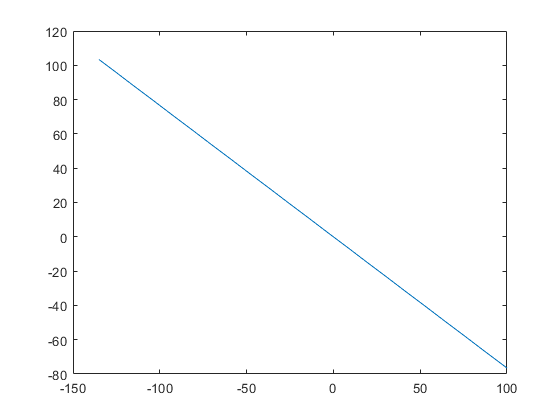


xaxis = -135:1:100;
y = tan(thetaC).*xaxis;
z = tan(deg2rad(120)).*xaxis;
plot(xaxis, y)